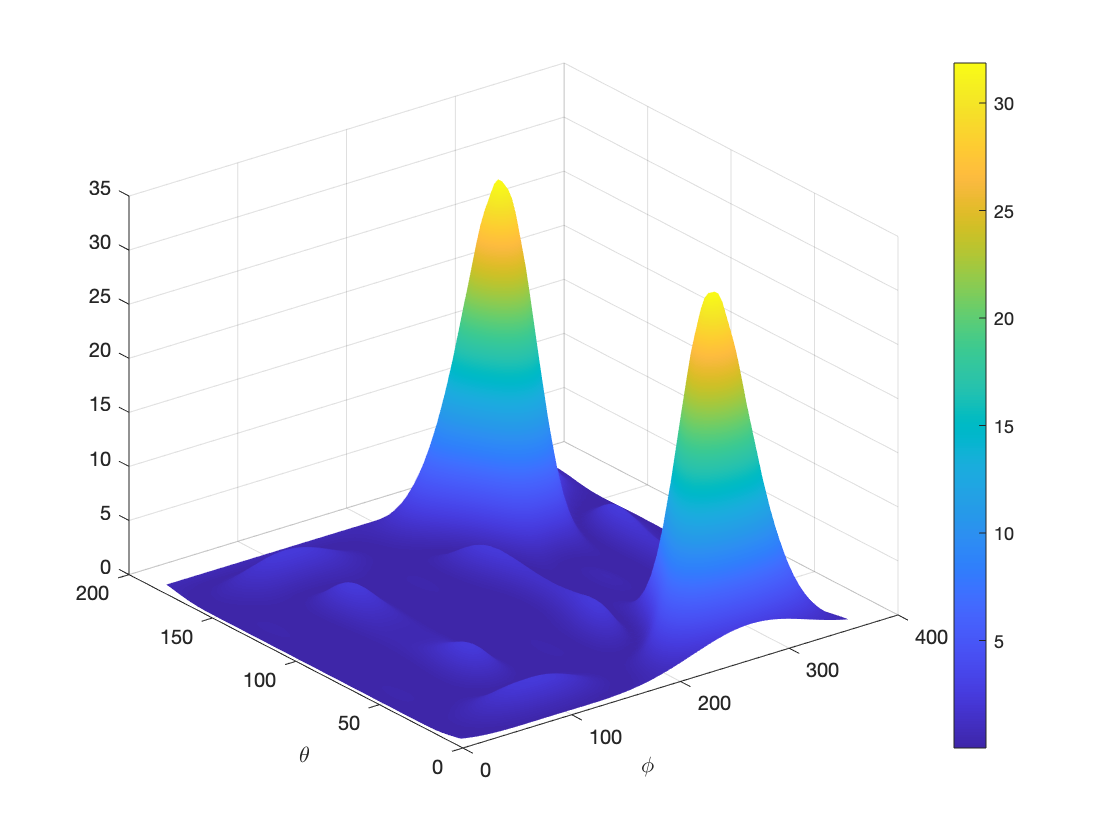

c=3e8;
f=1.8e9;
lambda=c/f;
dx=lambda/2; %distance between elements (X)
dy=lambda/2;%distance between elements (Y)
AB=[1 1 1 1;
    1 1 1 1;
    1 1 1 1;
    1 1 1 1]; % Array amplitudes
AB_phase=[0 80 160 240;
          0 80 160 240;
          0 80 160 240;
          0 80 160 240]*pi/180; %Array phases
AB_coe=AB.*(cos(AB_phase)+j*sin(AB_phase));
total_power=sum(sum(AB.^2))/2; 
%AF calculation
theta0=[pi/50:pi/50:pi];
phi0=[pi/50:pi/50:2*pi];
[phi,theta]=meshgrid(phi0,theta0);
sinU=sin(theta).*cos(phi);
sinV=sin(theta).*sin(phi);
AF_Field=0;
for n=1:4
    for m=1:4
        AF_Field = AB_coe(n,m)*exp(j*2*pi*(n-1)/lambda*dx*(sinU)).*exp(j*2*pi*(m-1)/lambda*dy*(sinV)) + AF_Field; 
    end
end
AF_power=AF_Field.^2;
AF_power_normalized=AF_power/total_power;
%Plotting
%mesh(phi0*180/pi,theta0*180/pi,20*log10(abs(AF)))
axis([0 360 0 180 -10 6])
surf(phi0*180/pi,theta0*180/pi,(abs(AF_power_normalized))), colorbar
xlabel('\phi')
ylabel('\theta')
shading interp